# Slice a Formal Table

Create a FormalTable object that contains employee data. Slice the table so that the first table column repeats in each slice and the maximum number of columns in each slice is three.

employee_data = {...
   'Joe Smith','3/12/06','Engineer','A302';...
   'Mary Jones','4/17/03','Writer','C312';...
   'John Johnson','9/5/12','Sr. Programmer','A421';...
   'Susan White','6/29/16','Sr. Engineer','B201';...
   'Thomas Lee','10/1/17','QE Engineer','C200'};
tbl_header = {'Name','Hire Date','Position','Office'};


import mlreportgen.report.*
import mlreportgen.dom.*
import mlreportgen.utils.*
     
rpt = mlreportgen.report.Report("Sliced Table",'pdf');
open(rpt);

chapter = Chapter("Title",'Employee Report');
table = FormalTable(tbl_header,employee_data);
table.Border = 'Solid';
table.RowSep = 'Solid';
table.ColSep = 'Solid';

para = Paragraph(['The table is sliced into two tables, '...
   'with the first column repeating in each table.']);
para.Style = {OuterMargin('0in','0in','0in','12pt')};
para.FontSize = '14pt';
add(chapter,para)

slicer = TableSlicer("Table",table,"MaxCols",3,"RepeatCols",1);
totcols = slicer.MaxCols - slicer.RepeatCols;
slices = slicer.slice();
for slice=slices
     str = sprintf('%d repeating column and up to %d more columns',...
          slicer.RepeatCols,totcols);
     para = Paragraph(str);
     para.Bold = true;
     add(chapter,para)
     add(chapter,slice.Table)
end

add(rpt,chapter)
close(rpt)
rptview(rpt)

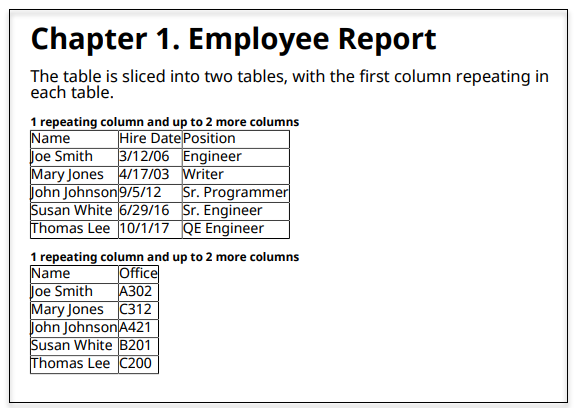

*Copyright 2018 The MathWorks, Inc.*